## Resistor-Inductor-Capacitor circuits

### 1. Series RLC

circuit = Circuit('circuits/passive/c6_rlc_series.txt');
circuit.list

ans =     'Vin 1 0 DC 5
     R1 3 0 1000
     L1 1 2 1
     C1 2 3 0.0001
     '


ELAB.analyze(circuit)

Symbolic analysis successful (0.272047 sec).


Say, you want expressions for node voltages.

circuit.symbolic_node_voltages

$$ans = \left(\begin{array}{c} v_{1}=\mathrm{Vin}\\ v_{2}=\frac{\mathrm{Vin}\,\left(C_{1}\,R_{1}\,s+1\right)}{C_{1}\,L_{1}\,s^{2}+C_{1}\,R_{1}\,s+1}\\ v_{3}=\frac{C_{1}\,R_{1}\,\mathrm{Vin}\,s}{C_{1}\,L_{1}\,s^{2}+C_{1}\,R_{1}\,s+1} \end{array}\right)$$

From the circuit, you can easily create a transfer function object, only giving the input and output nodes.

TF = ELAB.ec2tf(circuit, 1, 3)

Numerically evaluating circuit.

Numerical evaluation successful (0.0690117 sec).
Transfer function object created successfully (1.002254e-01 sec).

TF =
 
         1000 s
  --------------------
  s^2 + 1000 s + 10000
 
Continuous-time transfer function.



Matlab can then be used to visualize the circuit behavior as with any other system. Plotting the Bode diagram, we see that this circuit acts as a band-pass-filter.

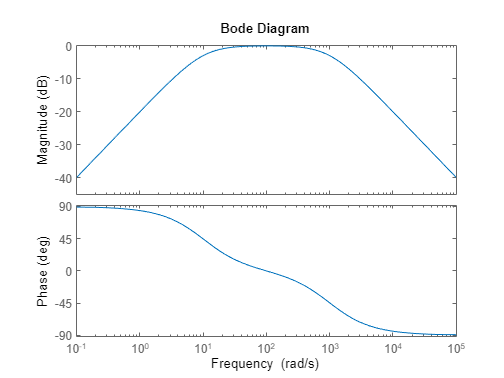

Transfer function object created successfully (2.338730e-02 sec).


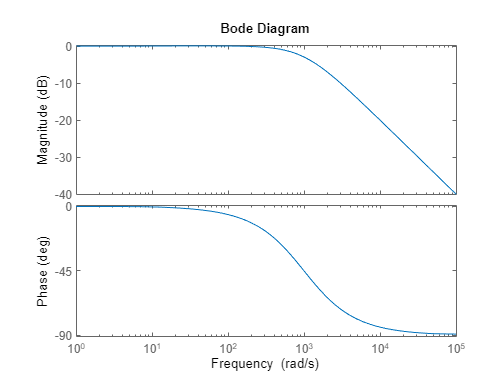

bode(TF)

### 2. Parallel RLC

We can repeat the process to look at RLC in parallel.

circuit = Circuit('circuits/passive/c7_rlc_parallel.txt');
circuit.list

ans =     'Iin 1 0 DC 2
     R1 1 0 1000
     L1 1 0 1
     C1 1 0 0.0001
     '


ELAB.analyze(circuit)

Symbolic analysis successful (0.166269 sec).


ELAB.evaluate(circuit)


Numerical evaluation successful (0.0415356 sec).


In this case, because there is only one node besides ground, the transfer function is just the voltage at node 1.

circuit.numerical_node_voltages(1)

$$ans = v_{1}=-\frac{2000\,s}{\frac{s^{2}}{10}+s+1000}$$

You can of course input the equation directly into Matlab's transfer function. Plotting the Bode diagram show that this is another kind of band-pass-filter.

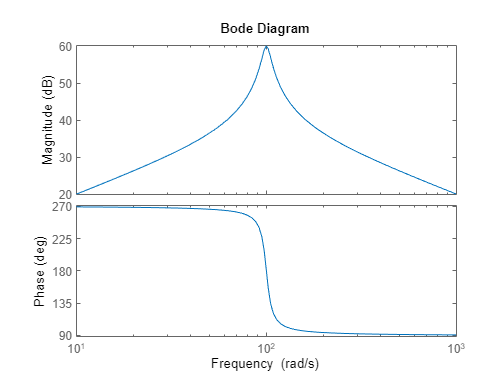

s = tf('s');
TF = -(1000*s)/(s^2/10 + s + 1000);
bode(TF)

Feel free to try any combination of resistors, capacitors and inductors. 